## 2.2 Calibration of a flat world, a homography 

**Home exercise A: How many points in the world (Xi , Yi) are, at least, needed to determine C?**

Since we need to solve 8 variables and each point gives 2 equations we need at least 4 points.

**Home exercise B: The camera should not be in wide angle mode. Why? **

This is a pinhole camera model

close all
clear

addpath("CameraCalibration1\")

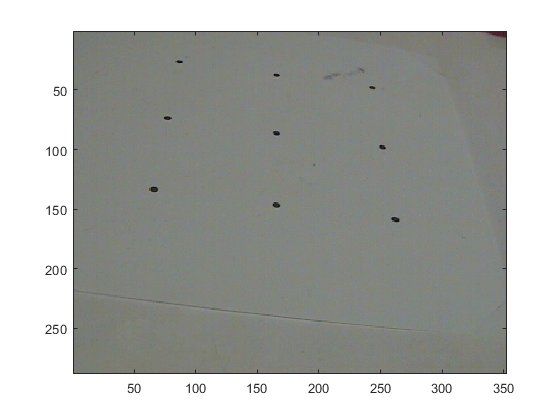

%open figures
f = openfig('calibrImage.fig');
f2 = figure;
set(f.Children,'Parent',f2)

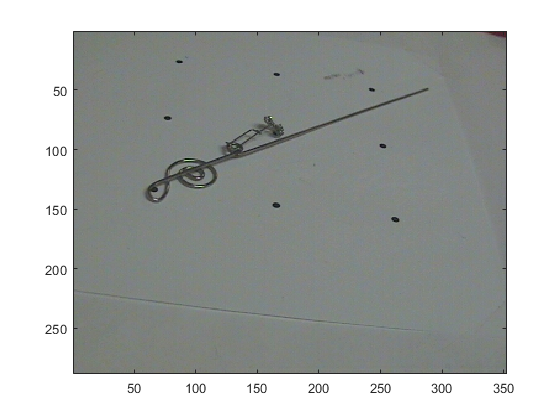

f = openfig('objectImage.fig');
f2 = figure;
set(f.Children,'Parent',f2)

**QUESTION 1: Which units are used for the world coordinates, inches, mm or cm? Listen to the cvl-cam-01 video! **

Centimeter

**QUESTION 2: Measure the positions of the calibration points in the image. Try to get sufficiently accurate values by zooming (with the magnifying glass) in the image.**

u1 = 87; v1 = 26; u2 = 166; v2 = 37; u3 = 243; v3 = 48; u4 = 77; v4 = 73; u5 = 165; v5 = 86; u6 = 251; v6 = 98; u7 = 66; v7 = 133; u8 = 165; v8 = 147; u9 = 262; v9 = 159;

**Home exercise C: You should soon calculate c through your calibration points and the pseudoinverse. The pseudoinverse of a matrix A is written A+. Write an equation which shows how c can be calculated from D and f.**


$$c = D^+f$$


% Calibration points in the world
%--------------------------------
X1 =  0; Y1 =  0;
X2 =  5; Y2 =  0;
X3 = 10; Y3 =  0;
X4 =  0; Y4 =  5;
X5 =  5; Y5 =  5;
X6 = 10; Y6 =  5;
X7 =  0; Y7 = 10;
X8 =  5; Y8 = 10;
X9 = 10; Y9 = 10;

% Calibration points in the image
%--------------------------------
u1 = 87; v1 = 26;
u2 = 166; v2 = 37;
u3 = 243; v3 = 48;
u4 = 77; v4 = 73;
u5 = 165; v5 = 86;
u6 = 251; v6 = 98;
u7 = 66; v7 = 133;
u8 = 165; v8 = 147;
u9 = 262; v9 = 159;

f = [u1 v1 u2 v2 u3 v3 u4 v4 u5 v5 u6 v6 u7 v7 u8 v8 u9 v9]';

% Calibration matrix
%-------------------
D = [  
    X1 Y1  1   0  0  0 -u1*X1 -u1*Y1;
     0  0  0  X1 Y1  1 -v1*X1 -v1*Y1;
    X2 Y2  1   0  0  0 -u2*X2 -u2*Y2;
     0  0  0  X2 Y2  1 -v2*X2 -v2*Y2;
    X3 Y3  1   0  0  0 -u3*X3 -u3*Y3;
     0  0  0  X3 Y3  1 -v3*X3 -v3*Y3;
    X4 Y4  1   0  0  0 -u4*X4 -u4*Y4;
     0  0  0  X4 Y4  1 -v4*X4 -v4*Y4;
    X5 Y5  1   0  0  0 -u5*X5 -u5*Y5;
     0  0  0  X5 Y5  1 -v5*X5 -v5*Y5;
    X6 Y6  1   0  0  0 -u6*X6 -u6*Y6;
     0  0  0  X6 Y6  1 -v6*X6 -v6*Y6;
    X7 Y7  1   0  0  0 -u7*X7 -u7*Y7;
     0  0  0  X7 Y7  1 -v7*X7 -v7*Y7;
    X8 Y8  1   0  0  0 -u8*X8 -u8*Y8;
     0  0  0  X8 Y8  1 -v8*X8 -v8*Y8;
    X9 Y9  1   0  0  0 -u9*X9 -u9*Y9;
     0  0  0  X9 Y9  1 -v9*X9 -v9*Y9];
 

**QUESTION 3: Give the vector c below!**

 % Calculate c
 c = pinv(D)*f

c =    16.0374
   -3.4589
   86.8665
    2.3470
    8.0291
   25.7072
    0.0017
   -0.0205


 c = [c; 1];
C = (reshape (c, 3, 3))'

C =    16.0374   -3.4589   86.8665
    2.3470    8.0291   25.7072
    0.0017   -0.0205    1.0000


test = C * [5 5 1]'

test =   149.7591
   77.5877
    0.9062


**QUESTION 4: Give the values (u5new, v5new) and (u5, v5).**

u5new = test(1) / test(3)

u5new = 165.2653

v5new = test(2) / test(3)

v5new = 85.6212

u5

u5 = 165

v5

v5 = 86

**QUESTION 5: Compare the values (u5new, v5new) and (u5, v5). They should conform fairly well. What are the reasons if they do not match perfectly?**

**QUESTION 6: Listen to the cvl-cam-01 video. What is the length of the real potato stick?**

17.6 cm.

**QUESTION 7: In the image, measure the two endpoints (ua, va) and (ub, vb) of the potato stick: **ua = 60; va = 138; ub = 288; vb = 49;

% (X/s, Y /s, 1/s) T = C−1 · (u, v, 1)'
% point a and b
a = inv(C)*[60, 138, 1]';
b = inv(C)*[288, 49, 1]';
a = a / a(3)

a =    -0.2334
   10.3866
    1.0000


b = b / b(3)

b =    13.0546
   -0.6901
    1.0000


**QUESTION 8: Determine the end points in world coordinates**. Xa = -0.2334; Ya = 10.3866; Xb = 13.0546; Yb = -0.6901;

**QUESTION 9: Which length does this corresponds to? Is this length similar to to real length?**

dist = sqrt((a(1)-b(1))^2+(a(2)-b(2))^2)

dist = 17.2992

 Quite similar.

**QUESTION 10: Mention some reasons why the real object length does not perfectly match the calculated length.**

This is an estimated camera matrix that will introduce error. There is also some variation depending on how the points were chosen in the image. Lastly since we are using pixels with integer values there will be some error.

## 2.3 Complete camera calibration

**Home exercise D: Look in generate homog.m, is the homographies solved with the homogeneous or inhomogenious solution? **

Inhomogeneous solution.

**Home exercise E: Look in homography2intrnsic.m and locate [U,S,V1] = svd(V); b = V1(:,6); b is related to B. How is A related to B? Check [2] or the lecture slides and give one equation! **


$$B = A^{-T} A^{-1}$$


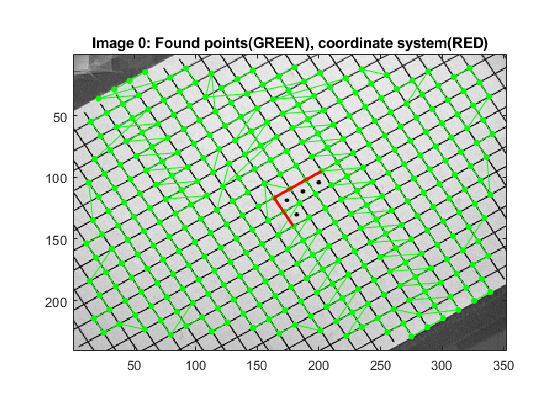

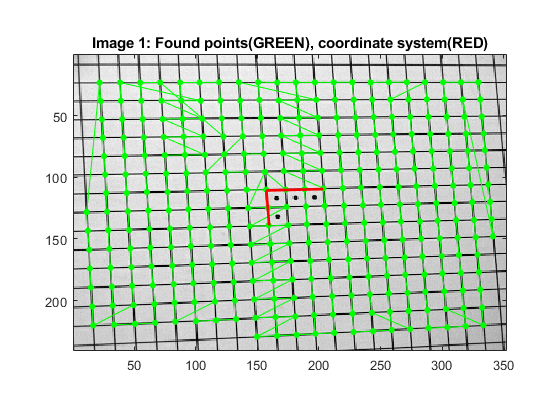

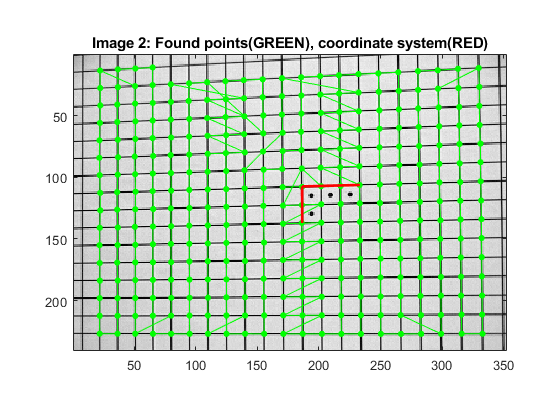

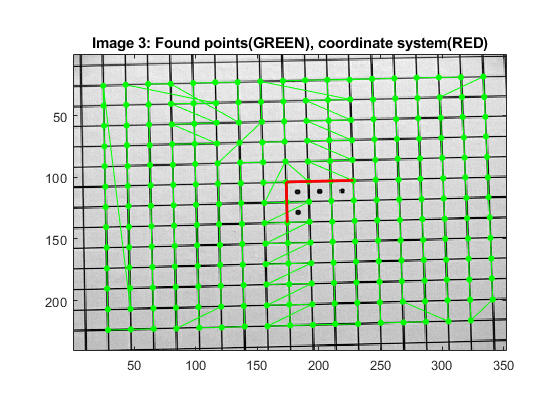

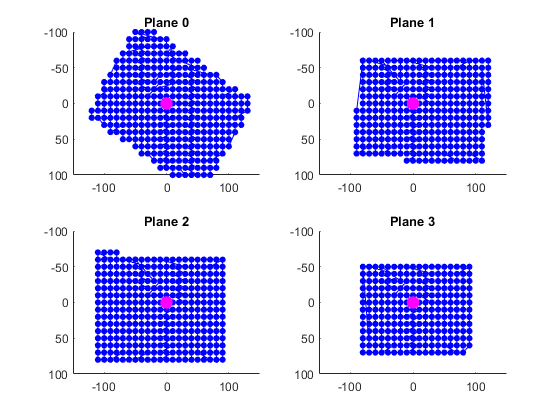

noPlanes = 4

A = 	1.0e+03 *

    1.2872   -0.0020    0.1898
         0    1.1672    0.1340
         0         0    0.0010


R =     0.8498    0.5255   -0.0147
   -0.5269    0.8505   -0.0034
    0.0107    0.0106    0.9997


t =   -17.4148
  -12.8092
  853.6756


run_norm


%save for later
A23 = A;
C23 = A*[R, t];

**QUESTION 11: What do you think that the points marked with green means? What do you think that the lines marked with red means? **

The green points are where it found cross sections between the lines and the red lines are where the coordinate system axises are.

**QUESTION 12: What do you think that the points marked with blue means? What do you think that the point marked with magenta means?**

The blue points are the coordinates for the green points in the images but homographically transformed to be seen orthogonally to the x-y coordinates. Magenta being the origin for the x-y system.

**Home exercise F: Calculate the distance between the camera center and the world coordinate system origin. Use A, R and/or t    **

norm(t)

ans = 853.9492

**QUESTION 13: Listen to the cvl-cam-00 video. What is the distance between the camera center (for simplicity, assume the rotation center) and the origin of the world coordinate system. Did you get consistency between calculation and measurement?**

It is similar at 83cm compared to 85.4cm.

**QUESTION 14: Listen to the cvl-cam-00 video. Where is the physical camera center located?**

It is in the apparent position of the aperture

**Home exercise G: Rotation between camera and world coordinate system has been performed almost exclusively around one axis. Which axis and how much rotation? Use A, R and/or t.**

Around the z-axis approximately 31 degrees.

**QUESTION 15: Listen to the cvl-cam-00 video. What is the rotation between the camera and the world coordinate system? Did you get consistency between calculation and measurement?**

The rotation is approximately 30 degrees so quite close.

**Home exercise H: What is the relationship between the pixel distances in the x- and y-direction. Use A, R and/or t.**

x_scale = A(1,1)

x_scale = 1.2872e+03

y_scale = A(2,2)

y_scale = 1.1672e+03

x_scale/y_scale

ans = 1.1027

**Home exercise I: The image size is 352×240, giving the center at (176.5, 120.5). Where is the correct center located, i.e. where does the optical axis intersect the image plane? Use A, R and/or t.**


$$s(u,v,1)^T = A[R,t]\cdot(X,Y,Z,1)^T
$$


% cent = A*[R,t]*[0,0,0,1]';
% cent = cent/cent(3)
cent = [A(1,3); A(2,3)]

cent =   189.8267
  134.0464


**Home exercise J: How big is the skew angle (ξ = arctan(γ/β)) between the image pixels? Give a measurement in degrees. Use A, R and/or t. **

skew = atand(A(1,2)/A(2,2))

skew = -0.0966

### 2.4 Complete camera calibration with zoomed lens

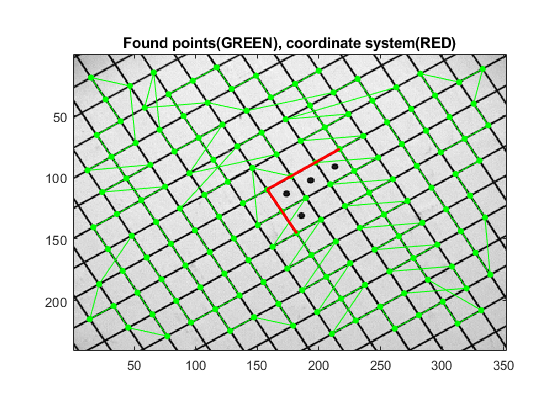

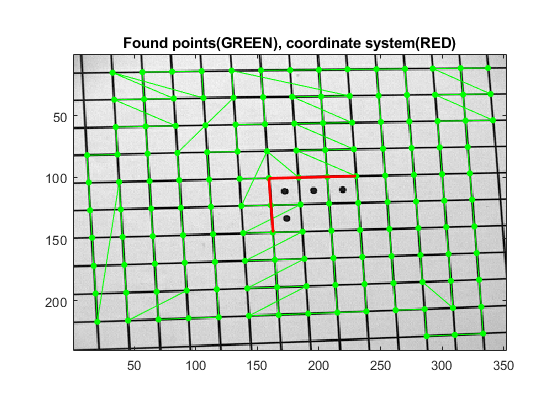

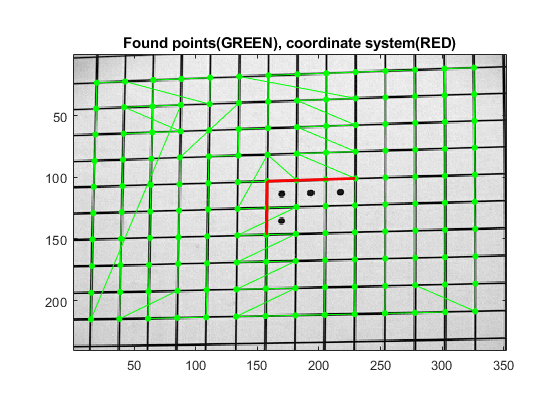

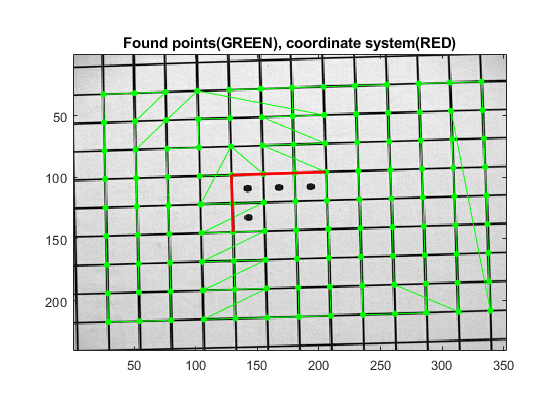

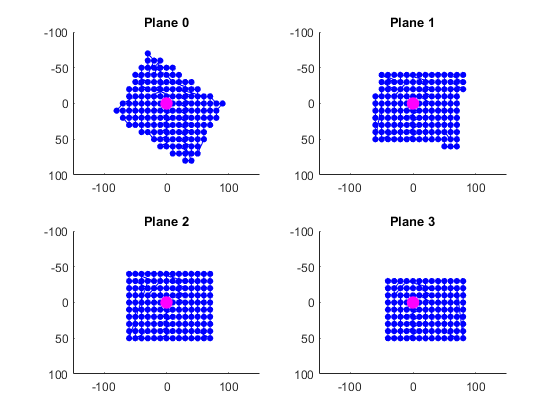

noPlanes = 4

A = 	1.0e+03 *

    2.0144   -0.0041    0.2253
         0    1.8249    0.1310
         0         0    0.0010


R =     0.8493    0.5261   -0.0225
   -0.5275    0.8508    0.0011
    0.0196    0.0109    1.0001


t =   -29.4055
  -10.0248
  879.2940


run_zoom

**QUESTION 16: We will now estimate how much larger the pixels are now compared to before. It is recommended to count the number of squares along the diagonals of im0.png and imz0.png to recive the relation.**

x=1 in im0: 28

x=1 in im0z: 18

So we get 

28/18

ans = 1.5556

**QUESTION 17: How much have the pixel size increased according to the matrices and is it in agreement with the above mentioned measurement?**

`A `

`10``3`` ×`

`    1.2872   -0.0020    0.1898`

`         0    1.1672    0.1340`

`         0         0    0.0010`

`Az`

`10``3`` ×`

`    2.0144   -0.0041    0.2253`

`         0    1.8249    0.1310`

`         0         0    0.0010`

2.0144/1.2872

ans = 1.5649

1.8249/1.1672

ans = 1.5635

It is close with 1.55 to 1.56

**QUESTION 18: Calculate the distance between the camera center and the world coordinate system origin. What can be the reason why the distance differ sligthy compared to before?**

norm(t)

ans = 879.8427

It is different since when we zoom the camera center changes.

**QUESTION 19: How big is the rotation according to the matrices now? It is approximately the same as before? **

It is approximately the same since we are just zooming in the z axis.

**QUESTION 20: What is the relationship between the pixel distances in the x- and y-direction? Is the measure approximately the same as before?**

x_scale = A(1,1)

x_scale = 2.0144e+03

y_scale = A(2,2)

y_scale = 1.8249e+03

x_scale/y_scale

ans = 1.1038

The relation is the same yes.

**QUESTION 21: The image size is 352×240, giving the center at (176.5, 120.5). Where is the correct image center located, i.e. where does the optical axis intersect the image plane? Compare with previous measurements. If it is not the same as before, try to give an explanation.**

% cent = A*[R,t]*[0,0,0,1]';
% cent = cent/cent(3)
cent = [A(1,3); A(2,3)]

cent =   225.2557
  130.9538


It is different. Likely due to the zoom not being perfectly on to the origin of the scene.

#### 2.5 To follow an object with the camera

**Home exercise L: See the four calibration images with their A-matrix in section 2.3 “Complete camera calibration”. Suppose that we have located an object at the coordinate (u, v) = (0, 0) in the image. How large angles, θu and θv, should the camera rotate to bring the object to the optical center of the image?**

normim_coord = pinv(A23)*[0,0,1]';
theta_u = atand(normim_coord(1)/1)

theta_u = -8.3992

theta_v = atand(normim_coord(2)/1)

theta_v = -6.5511

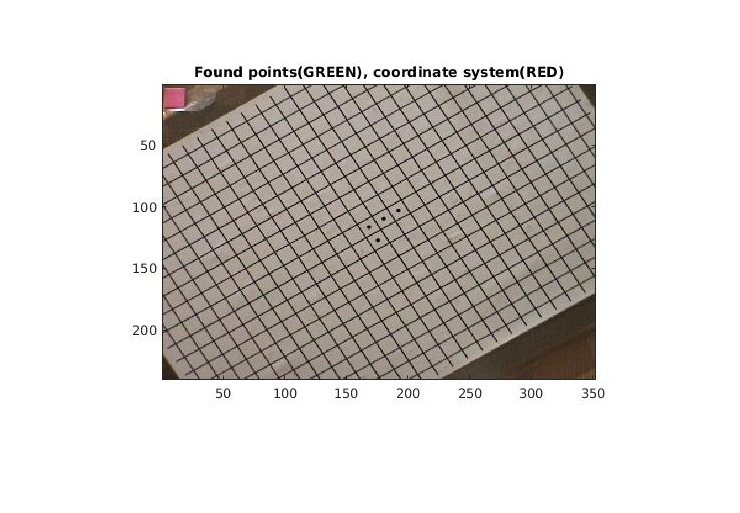


%show images
figure
imshow('basic.jpg')

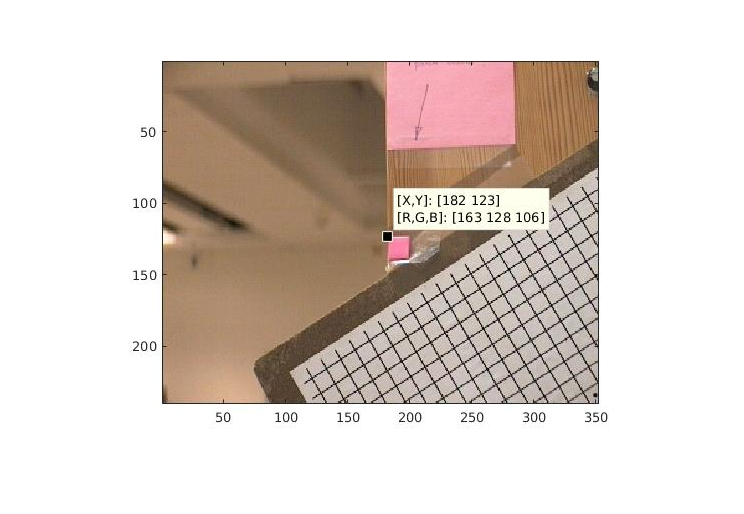

figure
imshow('rot2corner.jpg')

**QUESTION 22: In the image, measure the position of the optical center and compare it with the calibrated optical center. Do they agree?**

cent = [A23(1,3); A23(2,3)]

cent =   189.8267
  134.0464


Quite close.

### 2.6 Camera resectioning

**QUESTION 23: Take one set of A, R, t-matrices from section 2.3 “Complete camera calibration”. Multiply them together as C = A[Rt]. Now send C to P2KRt.m. What is the result?**

[K,R,t] = P2KRt(C23)

K = 	1.0e+03 *

    1.2865   -0.0030    0.1898
         0    1.1681    0.1340
         0         0    0.0010


R =     0.8500    0.5266   -0.0147
   -0.5267    0.8501   -0.0034
    0.0107    0.0106    0.9999


t =   -17.4220
  -12.7959
  853.8301


**QUESTION 24: This seems to be simpler than Zhang’s method. What is the advantage with Zhang’s method? **

It is cheap and simple to calibrate a camera with a simple print out and taking different photos of it to get the matrix.